**Configuration**

Add path for DMP and CasADi toolboxes

clear all; clc
experiment_number = 11;

[casadi_path, omf_path, dmp_path, dmp_path_obstacles] = load_paths();

% Add paths for DMP, OCP and CasADi dependencies
addpath(genpath(dmp_path));
addpath(genpath(omf_path));
addpath(genpath(casadi_path));
addpath(genpath(dmp_path_obstacles));

% OCP solver parameters and model parameters
[n_interval, t_final, scenario] = load_OCP_config(experiment_number)

n_interval = 300

t_final = 3

scenario = 1


% Define constants needed for the double pendulum
[m1, l1, m2, l2, Iz1, Iz2, r1, r2] = get_params_pendulum(scenario);

grav = 9.81; % gravity acceleration

% can we assume no damping ?
b1 = 0;  % damping coefficient of joint 1
b2 = 0;  % damping coefficient of joint 2

alpha = Iz1 + Iz2 + m1*r1^2 + m2*(l1^2+r2^2);
beta = m2*l1*r2;
delta = Iz2 + m2*r2^2;

% Integration time-step for reconstructing DMP
dt = 0.001;

% Define control-affine system of the form
% x' = f(x) + g(x)u  (1)
%
% NOTE: It is assumed that 'u' can be recovered from (1)    
%
%f = @(x) [-x(1)^2; -2*x(2)];
%g = @(x) [1 x(1); 0 1];
%F = @(x,u) f(x) + g(x)*u;

M = @(x) [alpha+2*beta*cos(x(2)), delta+beta*cos(x(2)); delta+beta*cos(x(2)), delta]

M = function_handle with value:
    @(x)[alpha+2*beta*cos(x(2)),delta+beta*cos(x(2));delta+beta*cos(x(2)),delta]



C = @(x) [-beta*sin(x(2))*x(4)+b1, -beta*sin(x(2))*(x(3)+x(4)); beta*sin(x(2))*x(3), b2]

C = function_handle with value:
    @(x)[-beta*sin(x(2))*x(4)+b1,-beta*sin(x(2))*(x(3)+x(4));beta*sin(x(2))*x(3),b2]



H = @(x) [m1*grav*r1*cos(x(1)) + m2*grav*(l1*cos(x(1)) + r2*cos(x(1)+x(2))); m2*grav*r2*cos(x(1)+x(2))]

H = function_handle with value:
    @(x)[m1*grav*r1*cos(x(1))+m2*grav*(l1*cos(x(1))+r2*cos(x(1)+x(2)));m2*grav*r2*cos(x(1)+x(2))]



f = @(x) [x(3); ...
          x(4); ...
          M(x)\ (-C(x) * [x(3); x(4)]- H(x))]

f = function_handle with value:
    @(x)[x(3);x(4);M(x)\(-C(x)*[x(3);x(4)]-H(x))]


g = @(x) [0 0;
          0 0;
          inv(M(x))]    % maybe a minus sign 

g = function_handle with value:
    @(x)[0,0;0,0;inv(M(x))]


F = @(x,u) f(x) + g(x)*u

F = function_handle with value:
    @(x,u)f(x)+g(x)*u


reverse_F = @(x,u) -f(x) - g(x)*u;


% Integrand of cost function
I = @(u) vecnorm(u').^2;

% Control input as a function of the state and its derivative
u_fcn_x_dx = @(x, dx) mldivide(g(x), (dx - f(x)));

n_states = 4;
n_inputs = 2;

% Choose DMP type:
% 1: Vanilla DMP proposed by Ijspeert et al. 2002
% 2: DMP using the time-varying stiffness modification proposed by Weitschat et al.
% 3: DMP with obstacles, based on the paper by Hoffmann et al.
DMP.type = 1;


% Obstacle position (in angles)
%obs_pos = pi/2;
%obs_pos = 0;
%obs_pos = [obs_pos, 0, 0];

**Sampling based on co-state and optimal value approximation**

Generate solutions for the parametrized optimal control problem

minimize $\int_{t_0}^{t_f}  \| u(s) \|^{2} ds$

s.t. $\dot{x} = F(x,u) = f(x) + g(x)u(x)$

      
$$x(t_0) = x_0$$


      
$$x(t_f) = x_1$$


where $x_1 \in \mathbb{P}$.

% Note: x_final will be moving while x_initial is kept constant
[x_initial, x_direction, x_final, N_samples, x_step, max_step, threshold] = load_OMF_config(experiment_number)

x_initial =     1.5708
    0.5236
         0
         0


x_direction =     1.5708
    1.5708
         0
         0


x_final =      0
     0
     0
     0


N_samples = 20

x_step = 0.0100

max_step = 5

threshold = 5

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:     8408
Number of nonzeros in inequality constraint Jacobian.:     2408
Number of nonzeros in Lagrangian Hessian.............:     6300

Total number of variables............................:     1804
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:     1208
Total number of inequality constraints...............:     1806
        inequality constraints with only lower bounds:      903
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:      903

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

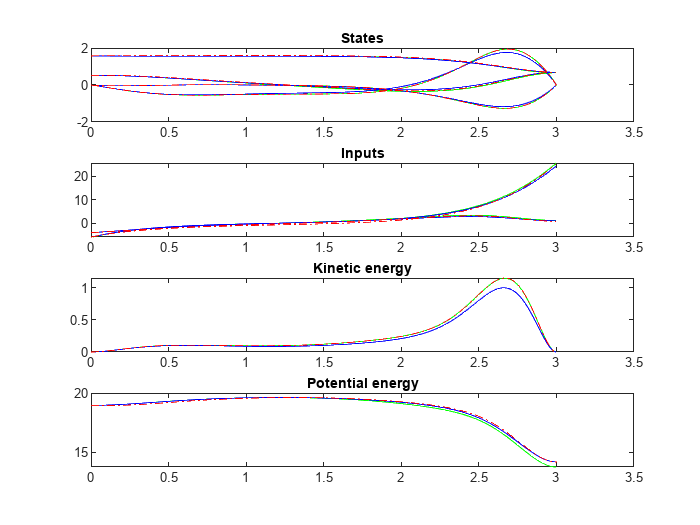

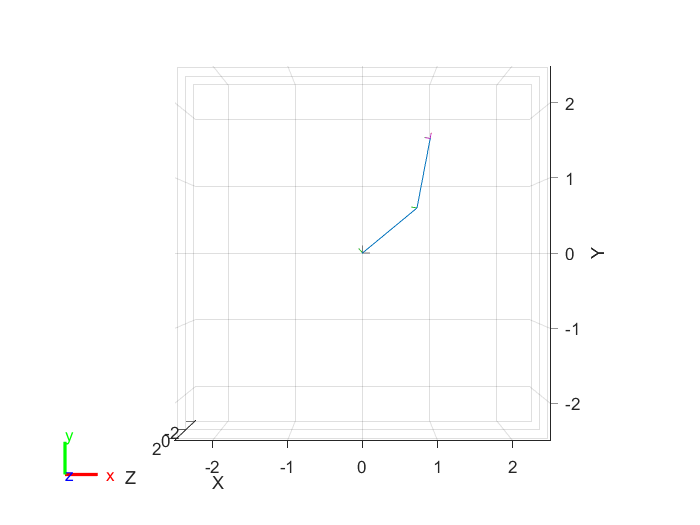


samples = {};
samples{1} = x_final;
n = 1;

% Initialize data for plotting
x_values = [];
optimal_costs = [];
estimated_costs = [];
DMP_costs = [];

% Start sampling algorithm
while n <= N_samples    

    x_values = [x_values x_final];

    % Sample backward solution from numerical solver 
    % Note: must transpose u_training and x_training before using with
    % other functions
    [time_training, u_training, x_training] = solve_OCP_direct_method(...
                reverse_F, ...    % System dynamics x' = F(x,u)
                n_states,   ...   % Number of states of system
                n_inputs,   ...   % Number of inputs of system
                n_interval, ...   % Number of control intervals
                [0 t_final], ...  % Time horizon
                x_final, ...      % Initial state
                x_initial);       % Terminal state

    % Kinetic and potential energy of the training solution
    for i = 1:size(x_training, 2)
        E_kin_training(i) = 0.5*[x_training(3, i) x_training(4, i)]*...
            [alpha+2*beta*cos(x_training(2, i)) delta+beta*cos(x_training(2, i)); delta+beta*cos(x_training(2, i)) delta]*...
            [x_training(3, i); x_training(4, i)];
        E_pot_training(i) = m1*grav*r1*sin(x_training(1,i))+...
            m2*grav*(l1*sin(x_training(1,i))+r2*sin(x_training(1,i)+x_training(2,i)));
    end

    % Pre-process optimal trajectory and encode in DMP
    trj = zeros(n_interval+1, n_states);
    for j=1:n_states
        for k=1:n_interval+1
            trj(k,j) = x_training(j,n_interval+2-k);
        end
    end   
    DMP.N = 80;
    if DMP.type == 1  | DMP.type == 3
        DMP = DMP_train(trj, time_training, DMP);
    elseif DMP.type == 2
        DMP = OMF_train(trj, time_training, DMP);
    end
    learned_DMP = DMP;           
    
    % Transpose the solution to use with auxilary functions
    u_training = u_training';
    x_training = x_training';
    
    % Co-state trajectory and optimal cost 
    p_training = compute_costate_rev(x_training(1:end-1,:), u_training, M); % must has the same size as u_training
    cost_training = compute_cost(u_training, time_training(1:end-1));    

    % Record costs at new sampling point
    optimal_costs = [optimal_costs cost_training];
    estimated_costs = [estimated_costs cost_training];
    DMP_costs = [DMP_costs cost_training];

    % Test DMPs in a h-neighborhood of sampled solution    
    n_step = 1;
    while 1    
        h = n_step*x_step;
        %size(p_training)
        % Compute a first-order approximation of optimal cost in x direction

        % !!! TO BE CHECKED AGAIN !!!
        estimated_V = cost_training + h*p_training(1,1);     %h*(p_training(1,:)'*x_direction(1:2, :)); %  
    
        % Compute DMP in this direction
        next_x = x_final + h*x_direction;
        x_values = [x_values next_x];
        estimated_costs = [estimated_costs estimated_V];
        learned_DMP.goal = next_x;
        [x_DMP, time_DMP] = DMP_trajectory(learned_DMP, dt, t_final, 1, l1, l2);
        u_DMP = DMP_compute_input(x_DMP, time_DMP, u_fcn_x_dx);

        DMP_cost = compute_cost(u_DMP', time_DMP);
        DMP_costs = [DMP_costs DMP_cost];
        
        % Kinetic energy for the DMP solution
        for i = 1:size(x_DMP, 1)
            E_kin_DMP(i) = 0.5*[x_DMP(i, 3) x_DMP(i, 4)]*...
                [alpha+2*beta*cos(x_DMP(i, 2)) delta+beta*cos(x_DMP(i, 2)); delta+beta*cos(x_DMP(i, 2)) delta]*...
                [x_DMP(i, 3); x_DMP(i, 4)];
            E_pot_DMP(i) = m1*grav*r1*sin(x_DMP(i,1))+...
                m2*grav*(l1*sin(x_DMP(i,1))+r2*sin(x_DMP(i,1)+x_DMP(i,2)));
        end
        % Compute cost of numerical solution for comparison
        [time_gt, u_gt, x_gt] = solve_OCP_direct_method( ...
                F, ...            % System dynamics x' = F(x,u)
                n_states,   ...   % Number of states of system
                n_inputs,   ...   % Number of inputs of system
                n_interval, ...   % Number of control intervals
                [0 t_final], ...  % Time horizon
                x_initial, ...    % Initial state
                next_x);          % Terminal state

        cost_gt = compute_cost(u_gt', time_gt(1:end-1));
        optimal_costs = [optimal_costs cost_gt];

        % Kinetic energy of the ground truth solution
        for i = 1:size(x_gt,2)
            E_kin_gt(i) = 0.5*[x_gt(3, i) x_gt(4, i)]*...
                [alpha+2*beta*cos(x_gt(2, i)) delta+beta*cos(x_gt(2, i)); delta+beta*cos(x_gt(2, i)) delta]*...
                [x_gt(3, i); x_gt(4, i)];
            E_pot_gt(i) = m1*grav*r1*sin(x_gt(1,i))+...
                m2*grav*(l1*sin(x_gt(1,i))+r2*sin(x_gt(1,i)+x_gt(2,i)));
        end


        % Plot input of DMP
        % plot(time_gt(1:end-1), u_gt, 'b-', ...
        %     time_DMP, u_DMP, 'r-.')

        % Plot DMP approximation for optimal trajectory
        subplot(4,1,1)
        plot(time_training, flipud(x_training), 'g', ...
             time_gt, x_gt, 'b-', ...
             time_DMP, x_DMP, 'r-.')
        title('States')
        %legend('xtraining', 'x_gt', 'x_DMP')

        % Plot the torques for the optimal trajectory, computed with DMP
        subplot(4,1,2)
        plot(time_training(:, 2:end), flipud(u_training)', 'g', ...
             time_gt(:,2:end), u_gt, 'b-', ...
             time_DMP, u_DMP, 'r-.')
        title('Inputs')
        %legend('u_training', 'u_gt', 'u_DMP')

        subplot(4,1,3)
        plot(time_training, flipud(E_kin_training'), 'g', ...
             time_gt, E_kin_gt, 'b-', ...
             time_DMP, E_kin_DMP, 'r-.')
        title('Kinetic energy')

        subplot(4,1,4)
        plot(time_training, flipud(E_pot_training'), 'g', ...
             time_gt, E_pot_gt, 'b-', ...
             time_DMP, E_pot_DMP, 'r-.')
        title('Potential energy')



        % Compare DMP cost with estimated optimal cost
        % If the difference is higher than a threshold prepare new sample, otherwise ignore
        % Also break the loop if the n_step has surpassed certain limit
        % because then the optimal cost estimator will lose too much precision
        if (abs(DMP_cost - estimated_V) >= threshold) || (n_step > max_step)
            % Record sample
            samples{n+1} = next_x;
            % Next iteration
            x_final = next_x;
            n = n + 1;
            break;
        end
        n_step = n_step + 1;
    end

    % Plot all the gifs 
    gif_filename = ['gifs_11/opt_2dof_pendulum' num2str(n) '.gif'];
    delete(gif_filename);
    % u_DMP
    % decrease size of trajectory by 10 in order to run faster
    anim_inc = 30;
    q_DMP = [x_DMP(1:anim_inc:end,1)';  % θ₁
             x_DMP(1:anim_inc:end,2)']; % θ₂

    plot_pendulum(scenario, q_DMP, gif_filename, 0)
end

**Visualization of results**

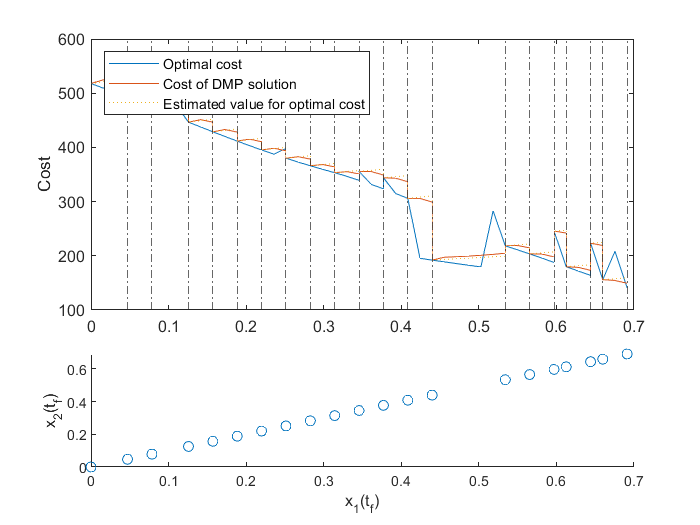

% figure;
% Convert sampling points to matrix
m_samples = cell2mat(samples);


% Compare cost of optimal solution with cost of DMP solution
subplot(3,1,1:2)
plot(x_values(1,:), optimal_costs, ...
     x_values(1,:), DMP_costs, ...
     x_values(1,:), estimated_costs, ':');

xline(m_samples(1,:),'-.');
legend('Optimal cost', 'Cost of DMP solution', 'Estimated value for optimal cost', 'Location', 'northwest');

ylabel('Cost');
%xlim([1,max(m_samples(1,:))])      

% Sampling grid 
subplot(3,1,3)
scatter(m_samples(1,:), m_samples(2,:));
% title('Sampling grid');
xlabel('x_1(t_f)');
ylabel('x_2(t_f)');

%xlim([1,max(m_samples(1,:))])

% Metrics
max_error = max(abs(optimal_costs - estimated_costs))

max_error = 118.5875

max_relative_error = max(abs(optimal_costs - estimated_costs)./optimal_costs) * 100

max_relative_error = 61.7507

min_diff_sample = min(diff(m_samples(1,:)))

min_diff_sample = 0.0157

total_samples_uniform = ceil((max(m_samples(1,:)) - 1) / min_diff_sample)

total_samples_uniform = -19


% Save data
save(['data/experiment_number' num2str(experiment_number) '.mat'])

% Plot animated gif of pendulum
% Here we consider the animation of the trajectory with initial state
disp('Initial state:')

Initial state:


disp(x_initial)

    1.5708
    0.5236
         0
         0



% and final state
disp('Final state:')

Final state:


disp(x_final)

    0.6912
    0.6912
         0
         0




% save as a gif
gif_filename = ['gifs/opt_2dof_pendulum' num2str(experiment_number) '.gif'];
delete(gif_filename);

% decrease size of trajectory by 10 in order to run faster
anim_inc = 10;
q_DMP = [x_DMP(1:anim_inc:end,1)';  % θ₁
         x_DMP(1:anim_inc:end,2)']; % θ₂

plot_pendulum(scenario, q_DMP, gif_filename, 0)